# RVC2: Chapter 15 - Visual Servoing

format compact
close all
clear
clc

## 15.2  Image-based visual servoing

## 15.2.1  Camera and image motion

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane



P = [1 1 5]';

p0 = cam.project( P )

p0 =    672
   672



px = cam.project( P, 'pose', SE3(0.1,0,0) )

px =    656
   672



( px - p0 ) / 0.1

ans =   -160
     0



( cam.project( P, 'pose', transl(0, 0, 0.1) ) - p0 ) / 0.1

ans =    32.6531
   32.6531



( cam.project( P, 'pose', trotx(0.1) ) - p0 ) / 0.1

ans =    40.9626
  851.8791



J = cam.visjac_p([672; 672], 5)

J =  -160.0000         0   32.0000   32.0000 -832.0000  160.0000
         0 -160.0000   32.0000  832.0000  -32.0000 -160.0000


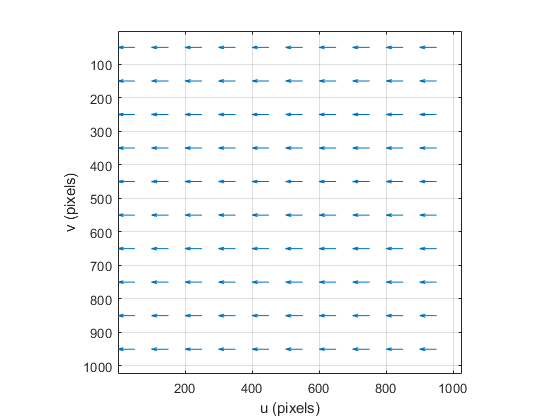



clf
cam.flowfield( [1 0 0 0 0 0] );

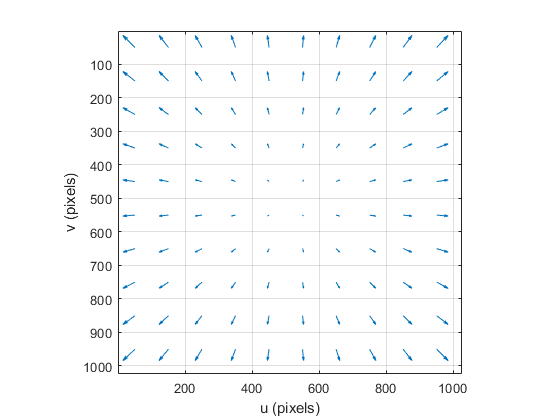


cam.flowfield( [0 0 1 0 0 0] );

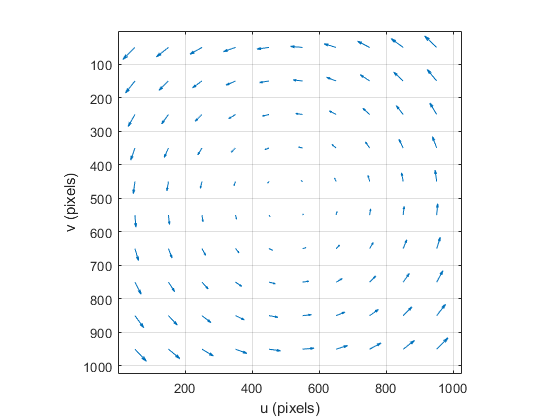


cam.flowfield( [0 0 0 0 0 1] );

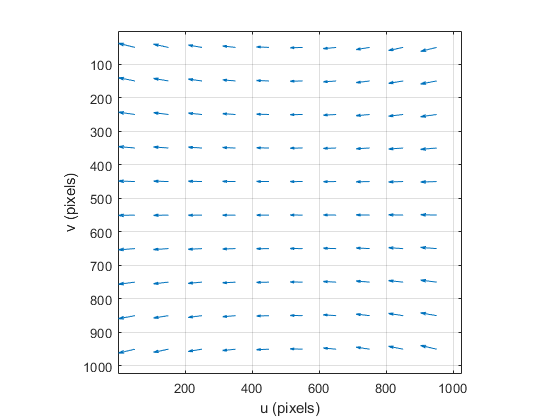


cam.flowfield( [0 0 0 0 1 0] );


cam.visjac_p(cam.pp', 1)

ans =  -800.0000         0         0         0 -800.0000         0
         0 -800.0000         0  800.0000         0         0


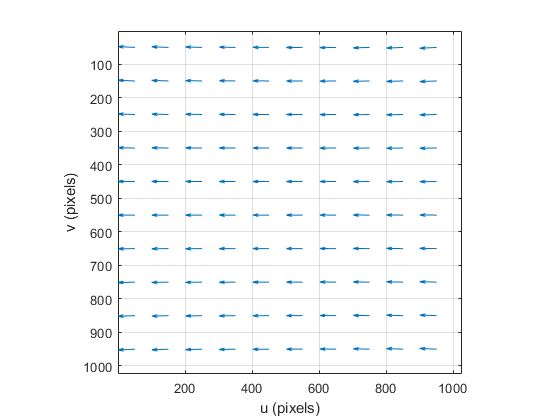


cam.f = 20e-3;
cam.flowfield( [0 0 0 0 1 0] );

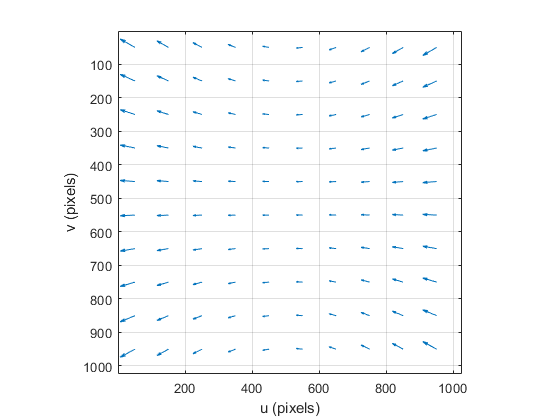


cam.f = 4e-3;
cam.flowfield( [0 0 0 0 1 0] );


J = cam.visjac_p(cam.pp', 1);
null(J)

ans =          0         0   -0.7071         0
         0    0.7071         0         0
    1.0000         0         0         0
         0    0.7071         0         0
         0         0    0.7071         0
         0         0         0    1.0000


## 15.2.2  Controlling feature motion

sl_ibvs

Unrecognized function or variable 'sl_ibvs'.


r = sim('sl_ibvs')

t = r.find('tout');
v = r.find('yout').signals(2).values;
about(v)

plot(t, v)

p = r.find('yout').signals(1).values;
about(p)
plot2(p)

## 15.2.4  Performance issues

pbvs.T0 = SE3(-2.1, 0, -3)*SE3.Rz(5*pi/4);
pbvs.run()

Reference to non-existent field 'run'.

ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', pbvs.T0, 'pstar', pd, 'lambda', 0.002, 'niter', Inf, 'eterm', 0.5)
ibvs.run()
ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', SE3(0,0, -1)*SE3.Rz(1), 'pstar', pd);
ibvs.run()
ibvs.plot_camera

ibvs = IBVS(cam, 'pose0',  transl(0,0, -1)*trotz(pi), ...
    'pstar', pd, 'niter', 10);
ibvs.run()
ibvs.plot_camera

bdclose('all')